## (a)

N1 = 14;
N2 = N1 + N1*0.2;

varN1 = N1/4;
varN2 = N2/4;

desvioN1 = sqrt(varN1);
desvioN2 = sqrt(varN2);

N1F = normrnd(N1,desvioN1,120,1);
round(N1F)

ans =     14
    13
    14
    15
    16
    14
    15
    14
    14
    15


N2F = normrnd(N2,desvioN2,120,1);
round(N2F)

ans =     18
    20
    17
    17
    20
    16
    17
    19
    17
    20


## (b)

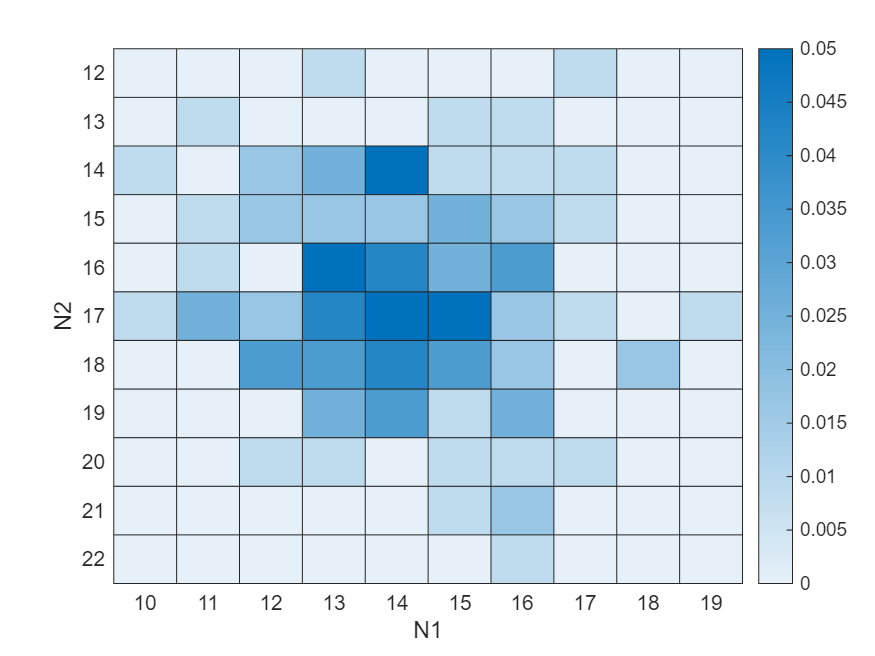

N1v = unique(round(N1F));
N2v = unique(round(N2F));

freq = zeros(length(N1v),length(N2v));

[~,N1m] = ismember(round(N1F),N1v); 
[~,N2m] = ismember(round(N2F),N2v);

for i = 1:length(N1F)
    freq(N1m(i),N2m(i)) = freq(N1m(i),N2m(i)) + 1;
end

prob= freq/120;

figure;
heatmap(N1v,N2v,prob');
xlabel("N1");
ylabel("N2");

## (c)

cov = cov(N1F,N2F);

sigma1 = std(N1F);
sigma2 = std(N2F);

corr = cov(1,2)/(sigma1*sigma2)

corr = 0.0779

## (d)

%nao sao independentes